# EH3DSB miniprojekt 1 – tidsdomæneanalyse

202200284 - Danni Raetzel

### **Indledning og formål**

I dette miniprojekt undersøges og analyseres tre forskellige lydklip i tidsdomænet. Formålet med opgaven er at blive fortrolig med håndtering, plottning og analyse af digitale signaler i MATLAB. Vi udfører analyse på de tre signaler, bestemmer deres egenskaber som antal samples, min- og max-værdier, RMS-værdier, energi, samt forskellen mellem venstre og højre kanal. Desuden udføres nedsampling og fade-out på et af signalerne. Projektet sigter mod at give indsigt i forskellige signalbehandlingsmetoder i tidsdomænet.

**Indlæsning af data**

load('miniprojekt1_lydklip.mat');

### 1. Aflytning af eksemplerne

% Lyt til signalerne (stop med 'clear sound')
%soundsc(s1, fs_s1);
%soundsc(s2, fs_s2);
%soundsc(s3, fs_s3);

### 2.Bestem antal samples for alle lydklip

Antallet af samples kan findes ved at kigge på længden af signalet

% Bestem antal samples
samples_s1 = length(s1);
samples_s2 = length(s2);
samples_s3 = length(s3);

disp(['Antal samples i s1: ', num2str(samples_s1)]);

Antal samples i s1: 1323000


disp(['Antal samples i s2: ', num2str(samples_s2)]);

Antal samples i s2: 3360000


disp(['Antal samples i s3: ', num2str(samples_s3)]);

Antal samples i s3: 1411200


### 3.Plot signalet med en tidsakse for alle lydklip

For at plotte signalet skal man oprette en tidsakse baseret på samplingsfrekvensen2

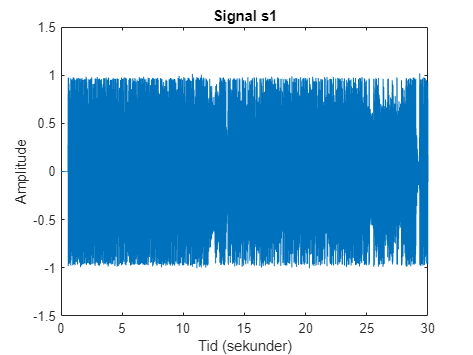

% Opret tidsakse
t_s1 = (0:length(s1)-1) / fs_s1;
t_s2 = (0:length(s2)-1) / fs_s2;
t_s3 = (0:length(s3)-1) / fs_s3;

% Plot signalet
figure;
plot(t_s1, s1(:,1));
xlabel('Tid (sekunder)');
ylabel('Amplitude');
title('Signal s1');

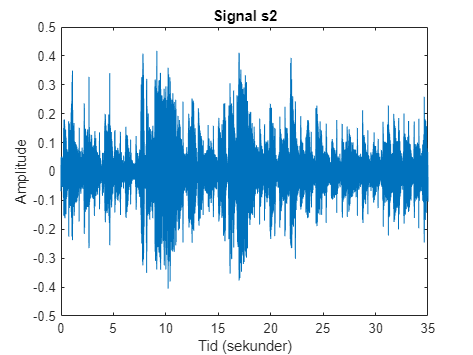


% Plot signal s2
figure;
plot(t_s2, s2(:,1));
xlabel('Tid (sekunder)');
ylabel('Amplitude');
title('Signal s2');

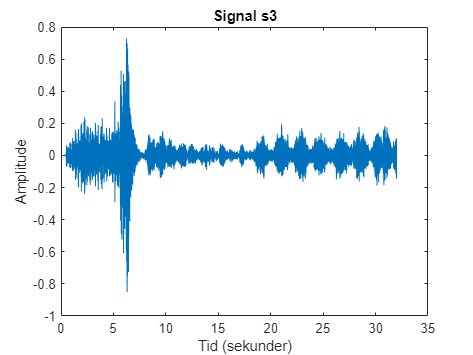


% Plot signal s3
figure;
plot(t_s3, s3(:,1));
xlabel('Tid (sekunder)');
ylabel('Amplitude');
title('Signal s3');

### 4.Bestem min- og max-værdi, RMS-værdi og energi for alle lyd lydklip

### Min- og max-værdier

%s1
min_s1 = min(s1(:,1));
max_s1 = max(s1(:,1));
%s2
min_s2 = min(s2(:,1));
max_s2 = max(s2(:,1)); 
%s3
min_s3 = min(s3(:,1));
max_s3 = max(s3(:,1)); 

### RMS-værdier

%s1
rms_s1 = rms(s1(:,1));
%s2
rms_s2 = rms(s2(:,1));
%s3
rms_s3 = rms(s3(:,1));

### Energi

%s1
energi_s1 = sum(s1(:,1).^2);
%s2
energi_s2 = sum(s2(:,1).^2);
%s3
energi_s3 = sum(s3(:,1).^2);

disp(['s1: ']);

s1: 


disp(['Min værdi: ', num2str(min_s1)]);

Min værdi: -1.0038


disp(['Max værdi: ', num2str(max_s1)]);

Max værdi: 1.019


disp(['RMS værdi: ', num2str(rms_s1)]);

RMS værdi: 0.32474


disp(['Energi: ', num2str(energi_s1)]);

Energi: 139515.5361



disp(['s2: ']);

s2: 


disp(['Min værdi: ', num2str(min_s2)]);

Min værdi: -0.40533


disp(['Max værdi: ', num2str(max_s2)]);

Max værdi: 0.41742


disp(['RMS værdi: ', num2str(rms_s2)]);

RMS værdi: 0.059926


disp(['Energi: ', num2str(energi_s2)]);

Energi: 12065.9997



disp(['s3: ']);

s3: 


disp(['Min værdi: ', num2str(min_s3)]);

Min værdi: -0.85016


disp(['Max værdi: ', num2str(max_s3)]);

Max værdi: 0.72832


disp(['RMS værdi: ', num2str(rms_s3)]);

RMS værdi: 0.046679


disp(['Energi: ', num2str(energi_s3)]);

Energi: 3074.8863


### 5.Beregn og lyt til forskellen mellem venstre og højre kanal.

Man kan finde forskellen/differencen ved at trække højre kanal fra den venstre.

% Beregn forskellen mellem venstre og højre kanal
difference_s1 = s1(:,1) - s1(:,2);


% Lyt til forskellen
%soundsc(s1, fs_s1);            % Lyd - Original
%soundsc(difference_s1, fs_s1); % Lyd - Forskellen

#### Beskriv hvad du hører

Når man lytter til forskellen mellem venstre og højre kanal, hører man mest de lyde, der er ude i siderne, da lydene i midten er fjernet. Det får lyden til at virke lavere og mere spredt sammenlignet med originalen

### 6.Nedsampling med faktor 4

Lav en ”nedsampling” af signalet med en faktor 4 og lyt til det nedsamplede signal2

% Definer den nye samplingsfrekvens som en fjerdedel af fs_s1
fs_ny = fs_s1 / 4;

% Nedsampler signalet fra den gamle samplingsfrekvens
s1_nedsamplet = resample(s1, fs_ny, fs_s1);


% Lyt til det nedsamplede signal
%soundsc(s1_nedsamplet, fs_ny);


#### Beskriv forskellen mellem det originale og det nedsamplede signal

Efter nedsampling med en faktor 4 lyder signalet mere forvrænget og mister detaljer i forhold til det originale. Den lavere samplingsfrekvens gør, at de høje frekvenser forsvinder, og det giver en ringere lydkvalitet.

### 7. Fade-out

Lav et ”fade-out” over den sidste tredjedel af signalet. Først lineært og dernæst eksponentielt aftagende Amplituden ved slutningen skal være 5 %

#### Lineært fade-out

% Definer fade-out perioden (sidste tredjedel af signalet)
N = length(s1);
fade_length = round(N / 3);
fade_start = N - fade_length + 1;

% Lav lineært fade-out
linear_fade = linspace(1, 0.05, fade_length)';
s1(fade_start:end, :) = s1(fade_start:end, :) .* linear_fade;

% Lyt til signalet med lineært fade-out
%soundsc(s1, fs_s1);

#### Plot af lineært fade-out

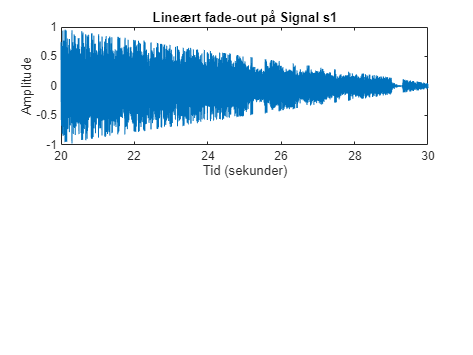

% Opret tidsakse for fade-out delen
t_fade = (fade_start:N) / fs_s1;

% Plot kun den del, der fader (lineært fade-out)
figure;
subplot(2, 1, 1);
plot(t_fade, s1(fade_start:end, 1));
xlabel('Tid (sekunder)');
ylabel('Amplitude');
title('Lineært fade-out på Signal s1');

#### Eksponentielt fade-out

% Lav eksponentielt fade-out
alpha = log(0.05) / fade_length; % Beregn alpha for 5% amplitude
exponential_fade = exp(alpha * (1:fade_length))';
s1(fade_start:end, :) = s1(fade_start:end, :) .* exponential_fade;

% Lyt til signalet med eksponentielt fade-out
%soundsc(s1, fs_s1);

#### Plot af eksponentielt fade-out

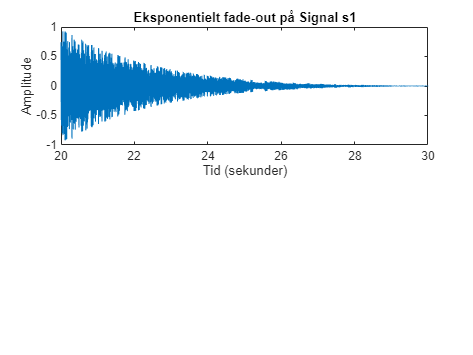

% Plot kun den del, der fader (eksponentielt fade-out)
figure;
subplot(2, 1, 1);
plot(t_fade, s1(fade_start:end, 1));
xlabel('Tid (sekunder)');
ylabel('Amplitude');
title('Eksponentielt fade-out på Signal s1');

#### Hvad lyder mest naturligt?

Det eksponentielle fade-out lyder mest naturligt, da lyden aftager gradvist og mere blødt mod slutningen. Det lineære fade-out virker mere pludseligt og kunstigt til sammenligning.

### Konklusion

I dette projekt har jeg analyseret tre lydklip i tidsdomænet ved hjælp af MATLAB. Jeg har beregnet antal samples, min- og max-værdier, RMS-værdier og energi. Jeg har også set på forskellen mellem venstre og højre kanal, hvor lyden i midten af stereobilledet blev fjernet. Nedsampling med en faktor 4 medførte et tab af detaljer og lavere lydkvalitet. Til sidst testede jeg både lineært og eksponentielt fade-out, hvor det eksponentielle lød mest naturligt.